# Debugging task data integrator

Something is off with my task data generating function `make_task_fmri.m`

Problem: second node is not coming on as expected despite having the same input as the other nodes.

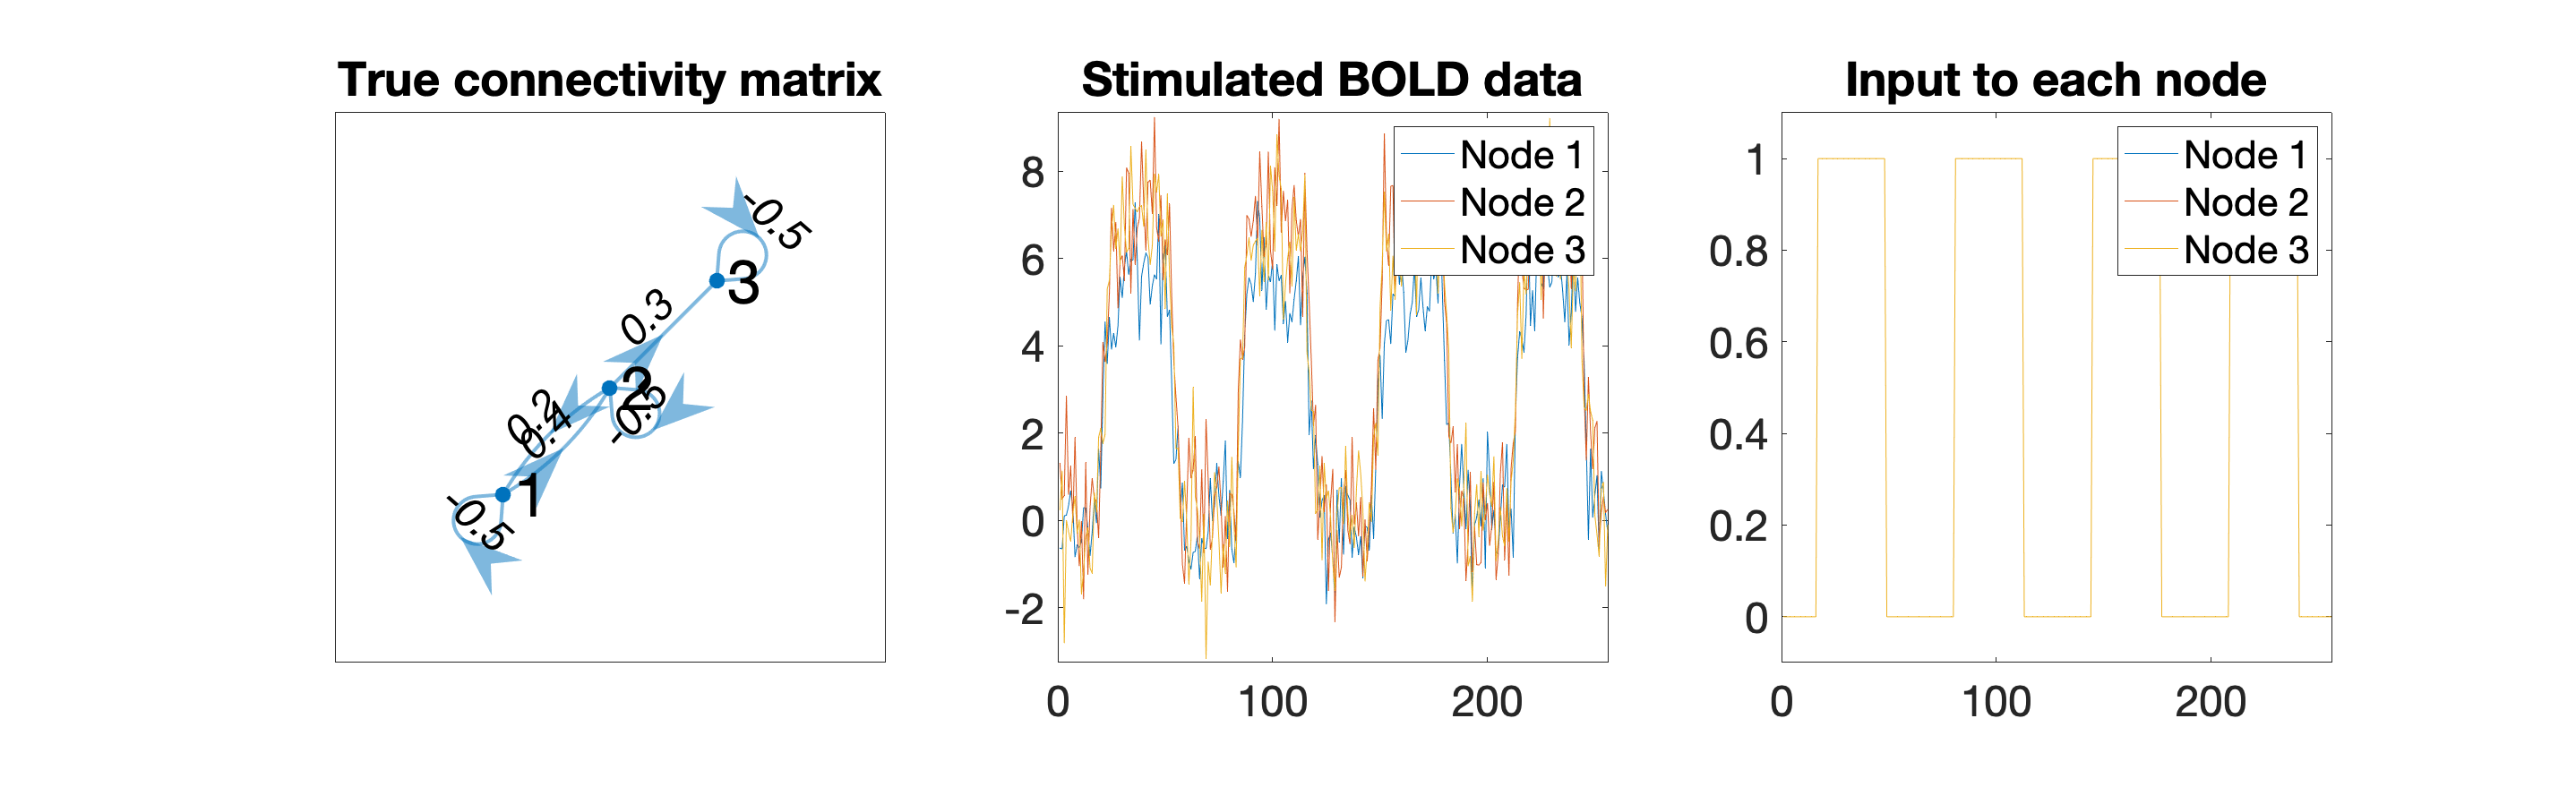

stim_options = get_default_stim_options();
on_len = 64;
off_len = 32;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = 1/8;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = [1,2,3];
stim_options.c = eye(stim_options.n);
stim_options.u = zeros(length(tasktiming), stim_options.n);
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

[DCM, options] = make_task_fmri(stim_options);
plot_sim_data(DCM)

In `spm_fx_fmri.m` flow should be 

What does the flow into node 2 look like? Flow looks the same for nodes 1 and 3 but different for node 2. Which component of flow is different? Task bit (expectedly) is the same for all nodes but the network bit is different. 

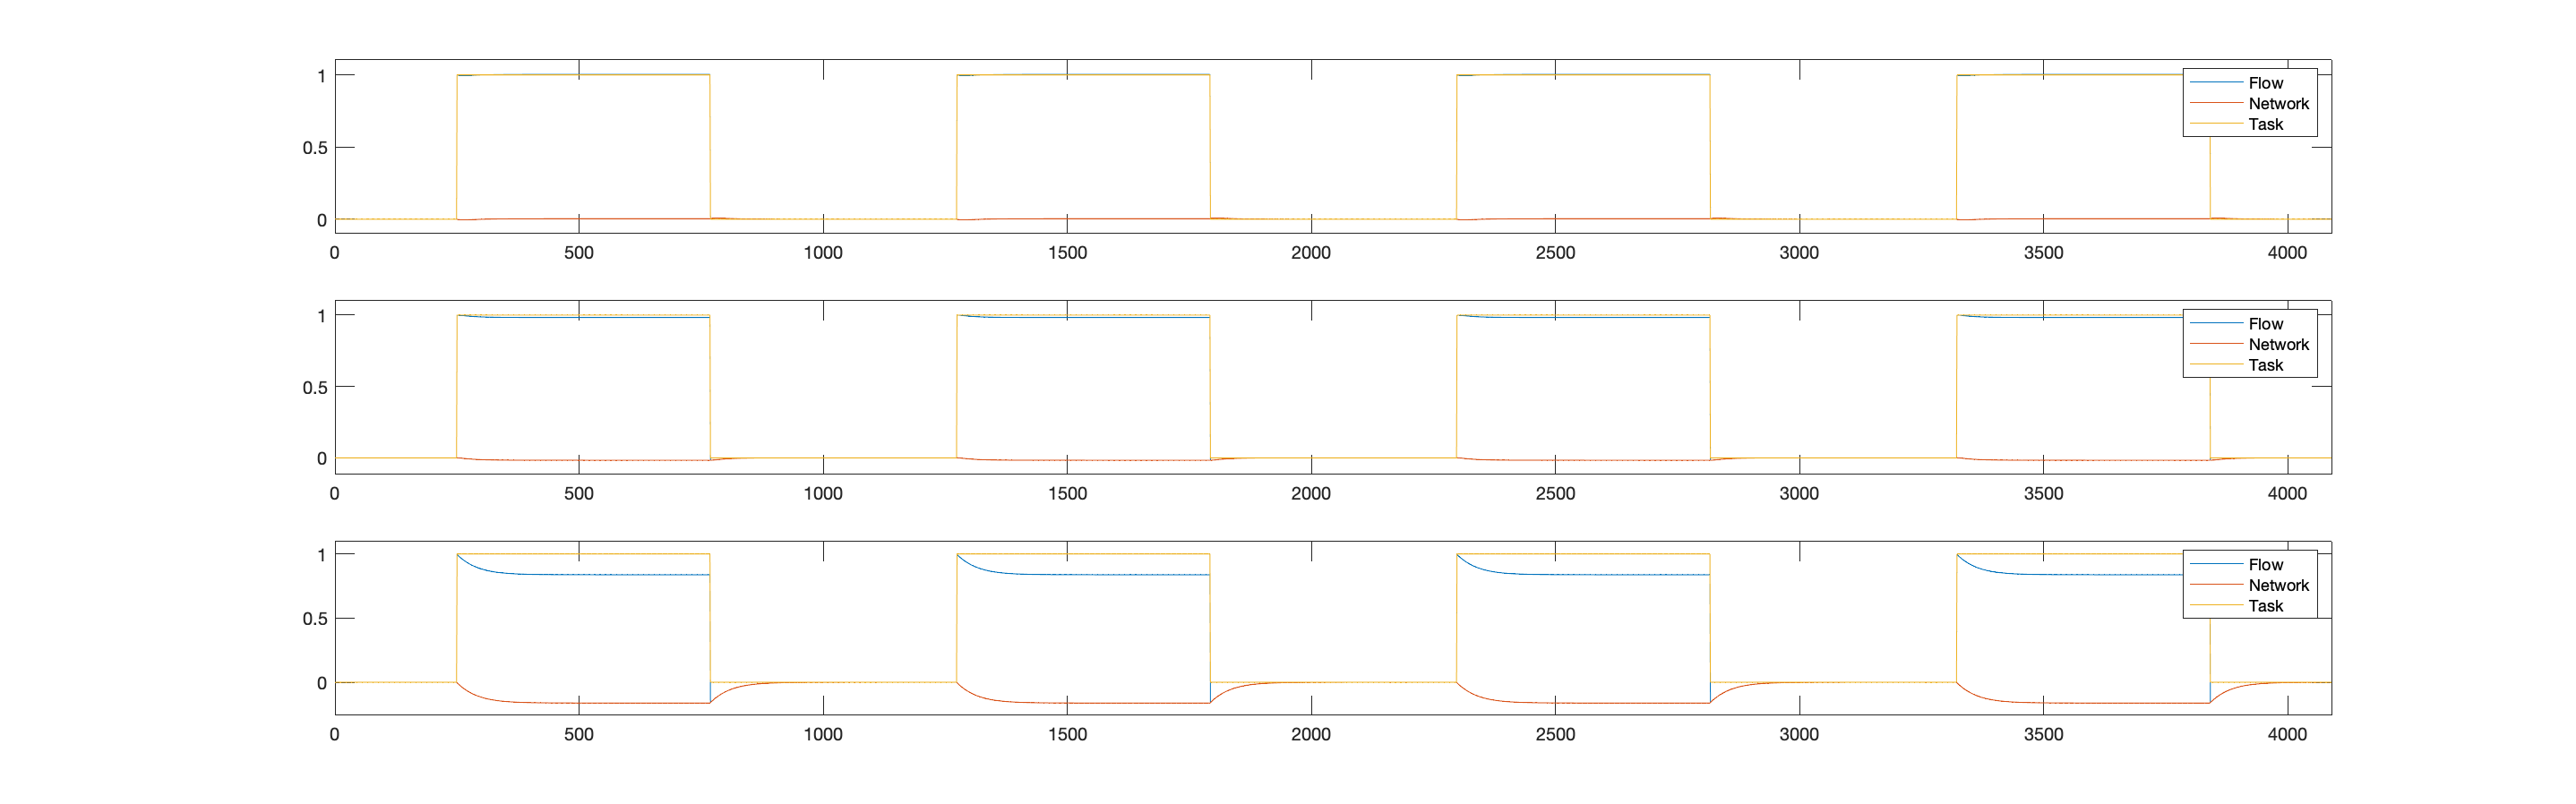

net_contrib = DCM.x*DCM.Tp.A;
task_contrib = DCM.U.u*DCM.Tp.C;
flow =  net_contrib + task_contrib;

for i=1:stim_options.n
    subplot(3,1,i)
    plot(flow(:,i))
    hold on
    plot(net_contrib(:,i))
    hold on
    plot(task_contrib(:, i))
    legend("Flow", "Network", "Task")
    axis([0 size(flow, 1) min(flow(:, i))-0.1 max(flow(:, i))+0.1 ])
end

Prune the network and see if each nodes behaves the way you expect **without any connections between them only with inhibitory self connections**. NODE 2 IS STILL BROKEN?!

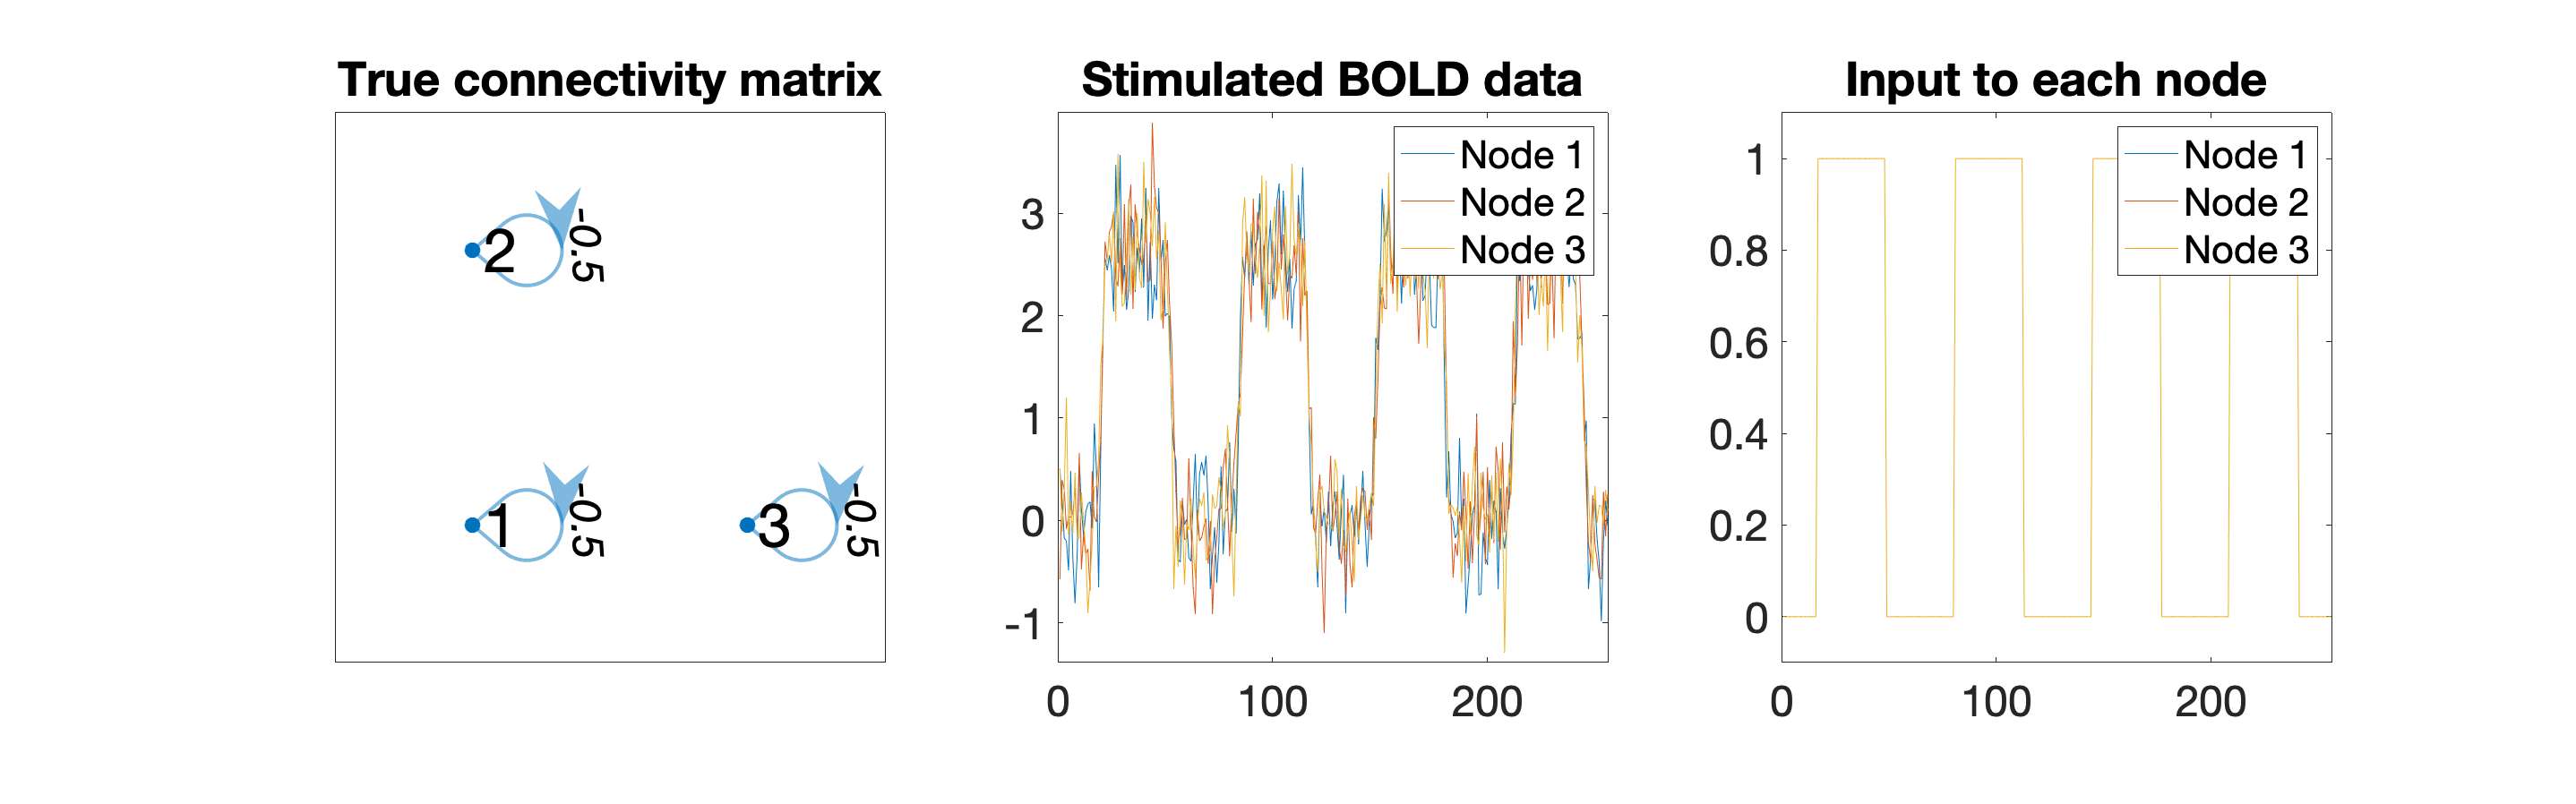

stim_options.Tp.A = zeros(stim_options.n);
[DCM, options] = make_task_fmri(stim_options);
plot_sim_data(DCM)

What if stimulation is only onto node 2 and there is no connectivity? This is messed up. 

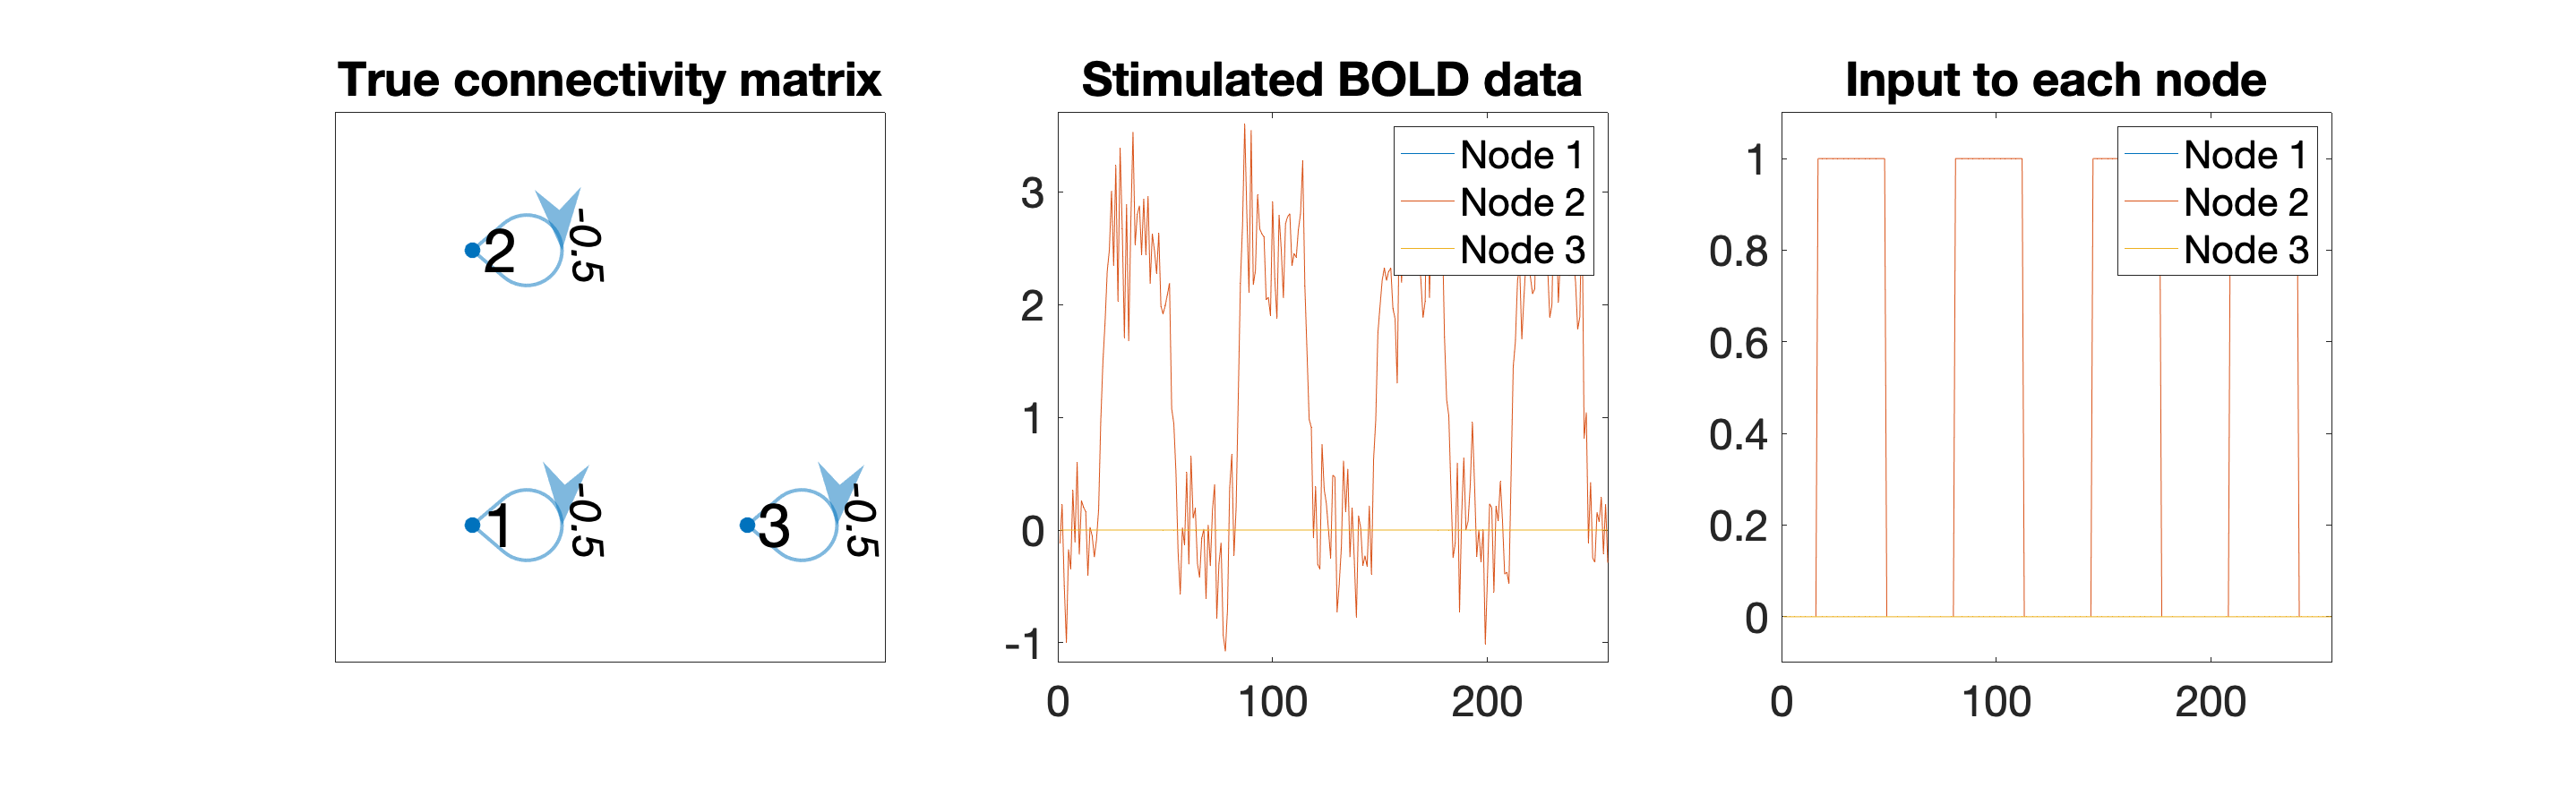

stim_options.u(:, 1) = zeros(size(stim_options.u,1), 1);
stim_options.u(:, 3) = zeros(size(stim_options.u,1), 1);
[DCM, options] = make_task_fmri(stim_options);
plot_sim_data(DCM)